clear 
clc

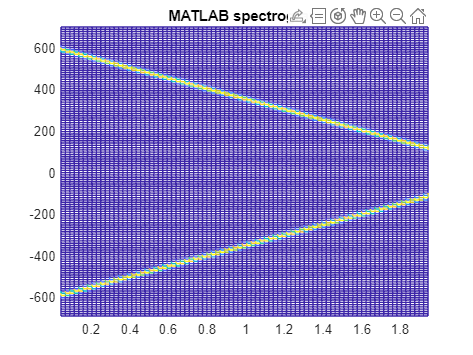

fs = 1400;
x = chirp(0:1/fs:2,600,2,100);
M = 128;
g = hann(M,"periodic");
L = 0.75*M;
Ndft = 128; 

[S1,F1,T1] = spectrogram(x,g,L,Ndft,fs,"centered"); 
mesh(T1,F1,abs(S1).^2)
title("MATLAB spectrogram")
view(2), axis tight

[S2, F2, T2]=MYstft(x, fs, g, 75, Ndft)

S2 =    0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i   0.0001 + 0.0000i  -0.0000 + 0.0000i   0.0002 + 0.0000i   0.0000 + 0.0000i  -0.0002 + 0.0000i  -0.0000 + 0.0000i  -0.0002 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0002 + 0.0000i   0.0002 + 0.0000i  -0.0002 + 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i  -0.0001 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0002 + 0.0000i   0.0000 + 0.0000i  -0.0004 + 0.0000i   0.0003 + 0.0000i  -0.0006 + 0.0000i  -0.0004 + 0.0000i   0.0005 + 0.0000i  -0.0002 + 0.0000i   0.0001 + 0.0000i
   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0

F2 = 1.0e+03 *

         0
    0.0109
    0.0219
    0.0328
    0.0437
    0.0547
    0.0656
    0.0766
    0.0875
    0.0984


T2 =          0
    0.0229
    0.0457
    0.0686
    0.0914
    0.1143
    0.1371
    0.1600
    0.1829
    0.2057


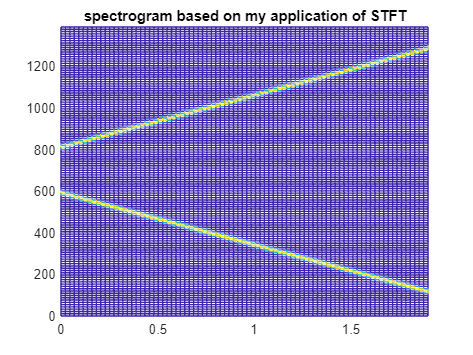

mesh(T2,F2,abs(S2).^2)
title("spectrogram based on my application of STFT")
view(2), axis tight

Fs = 1e3;
t = 0:1/Fs:1;
z = exp(1i*2*pi*32*t).*(t>=0.1 & t<0.3)+2*exp(-1i*2*pi*64*t).*(t>0.7);
wgnNoise = 0.05/sqrt(2)*randn(size(t))+1i*0.05/sqrt(2)*randn(size(t));
z = z+wgnNoise;

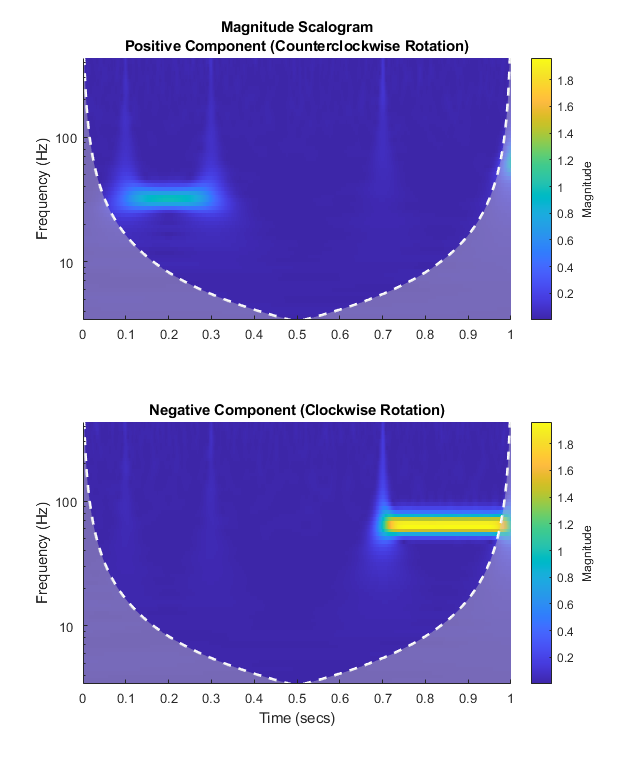

cwt(z,Fs)

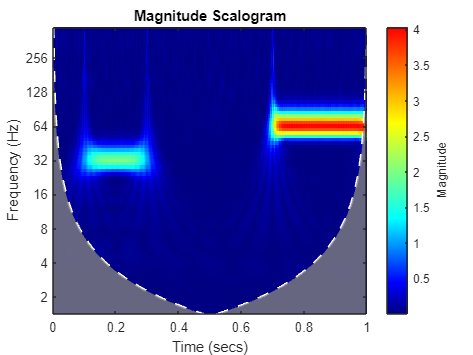

MYcwtOrg(z,Fs,'morlet');